Robot 2 - 3 GDL 1 Angular y 2 Prismáticos 

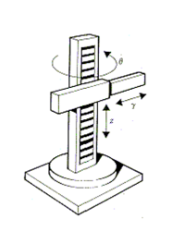

En este robot podemos notar 3 grados de libertad, donde el primero de ellos es rotacional y las otras dos son prismaticas, es por eso su importancia en la declaración de RP con sus valores especificos, de igual forma nuestras variables son theta y 2 longitudes.

%Limpieza de pantalla
clear all
close all
clc

%Declaración de variables simbólicas
syms th1(t) l2(t) l3(t) t

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP =[0 1 1];

%Creamos el vector de coordenadas articulares
Q = [th1 l2 l3];

%Creamos el vector de velocidades generalizadas
Qp = diff(Q, t);

%Número de grado de libertad del robot
GDL = size(RP,2);
GDL_str = num2str(GDL);

Para declarar nuestras articulaciones, tomamos planteamos que nuestro plano cartesiano está con z perpendicular a nuestra rotacion, por lo que el cambio de posicion es un dezplazamiento 0 en en z pero desplazamiento angular en X, Y estos con sus respectivos coseno y seno, Para el dezplazamiento rotacional solo z se encuentra en movimiento, por lo que colocamos su matriz correspondiente. 

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [cos(th1); sin(th1); 0];
%Matriz de rotación de la junta 1 respecto a 0
R(:,:,1)= [cos(th1) -sin(th1) 0;
           sin(th1) cos(th1) 0;
           0 0 1];

Respecto a nuestra segunda articulación, tenemos solo un dezplazamiento de l2, que es nuestra segunda articulación y tenemos igualmente una rotacion de -90° en Y, esto porque ajustamos nuestro z en direccion de nuestra terminación. Para esta matriz, podemos calcular directamente el resultado, dando 0 en cosenos y -1 en senos, resultando en la siguiente matriz.

%Articulación 2 
%Posición de la articulación 2 respecto a 1
P(:,:,2)= [0; 0; l2];
%Matriz de rotación de la junta 2 respecto a 1
R(:,:,2)= [1 0 0;
           0 0 1
           0 -1 0];

Nuestra ultima articulación es prismatica por lo que no tendrá que rotar pero si trasladarse, por lo que usamo l3 para definir su movimiento, en esta ocasion en Y.

%Articulación 3
%Posición de la articulación 3 respecto a 2
P(:,:,3)= [0; l3; 0];
%Matriz de rotación de la junta 3 respecto a 2
R(:,:,3)= [1 0 0;
           0 1 0;
           0 0 1];

Se generar las matrices de trasnformación homogeneas globales y locales, se utiliza igualmente un Vector de relleno para completar la matriz y que no genere errores en calculos.

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);
%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

Se inicializan los valores de los vectores de posición y de rotación (vistos desde el marco de referencia inercial).

%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 

Se crean mediante un loop de los GDL el calculo de las matricez de transformacion locales de cada junta y posterior calcular la Global a partir de la local anterior.

%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 
for i = 1:GDL
    i_str= num2str(i);   
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   
   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))
    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
end

Matriz de Transformación global T1


/ cos(th1(t)), -sin(th1(t)), 0, cos(th1(t)) \
|                                           |
| sin(th1(t)),  cos(th1(t)), 0, sin(th1(t)) |
|                                           |
|      0,            0,      1,      0      |
|                                           |
\      0,            0,      0,      1      /



Matriz de Transformación global T2


/ cos(th1(t)),  0, -sin(th1(t)), cos(th1(t)) \
|                                            |
| sin(th1(t)),  0,  cos(th1(t)), sin(th1(t)) |
|                                            |
|      0,      -1,       0,         l2(t)    |
|                                            |
\      0,       0,       0,           1      /



Matriz de Transformación global T3


/ cos(th1(t)),  0, -sin(th1(t)),  cos(th1(t))  \
|                                              |
| sin(th1(t)),  0,  cos(th1(t)),  sin(th1(t))  |
|                                              |
|      0,      -1,       0,      l2(t) - l3(t) |
|                                              |
\      0,       0,       0,            1       /



El resultado obtenido en estas matrices es importantes debido a que nos guia sobre como está colocandose y dependiendo mutuamente del resto de articulaciones, podemos ver resultados de desplazamiento correctos para la primera matriz debido a que solo existe rotacion y no hay ningún multiplicador en los posiciones. Para nuestra segunda, manetenmos el mismo movimiento, pero debido a realizar una rotación, las ubicaciones de nuestras rotaciones son afectadas adecuadamente, aunque tenemos  desplazamiento en nuestro z, es decir, nuestra primera altura, para la tercera matriz global y nuestro resultado final, tenemos cambios en los ejes correspondientes a su posicion y rotacion.

Calculamos los Jacobianos, usamos el metodo lineal con diferenciacion. Lo que nos genera 9 derivadas parciales por los 3 ejes. Como resultado, obtenemos la matriz de resultados en Jv_d y lo imprimimos.

Jv11= functionalDerivative(PO(1,1,GDL), th1);
Jv12= functionalDerivative(PO(1,1,GDL), l2);
Jv13= functionalDerivative(PO(1,1,GDL), l3);
%Derivadas parciales de y respecto a th1, l2 y l3
Jv21= functionalDerivative(PO(2,1,GDL), th1);
Jv22= functionalDerivative(PO(2,1,GDL), l2);
Jv23= functionalDerivative(PO(2,1,GDL), l3);
%Derivadas parciales de z respecto a th1, l2 y l3
Jv31= functionalDerivative(PO(3,1,GDL), th1);
Jv32= functionalDerivative(PO(3,1,GDL), l2);
Jv33= functionalDerivative(PO(3,1,GDL), l3);
%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13; 
              Jv21 Jv22 Jv23; 
              Jv31 Jv32 Jv33]); 
%Matriz Jacoviano Lineal
pretty(jv_d);

/ -sin(th1(t)), 0,  0 \
|                     |
|  cos(th1(t)), 0,  0 |
|                     |
\       0,      1, -1 /



Procedemos a calcularlo analiticamente mediente un ciclo for para poder obtener las velocidades angulares y lineales. Debido a que existen primeros casos debemos colocar un try para no tomar en cuenta posiciones fuera del array, es decir, i-1.

%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);
for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    
Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);


Una vez finalizados los jacobianos podemos obtener las velocidaddes angular y lineales solo multiplicando por nuestro Qp. 

%Velocidad lineal obtenida mediante el Jacobiano lineal
V=simplify (Jv_a*Qp');
pretty(V);

/              / ________   _________ \ \
|              |  d          d        | |
| -sin(th1(t)) | -- l3(t) + -- th1(t) | |
|              \ dt         dt        / |
|                                       |
|              / ________   _________ \ |
|              |  d          d        | |
|  cos(th1(t)) | -- l3(t) + -- th1(t) | |
|              \ dt         dt        / |
|                                       |
|                ________               |
|                 d                     |
|                -- l2(t)               |
\                dt                     /




%Velocidad angular obtenida mediante el Jacobiano angular
W=simplify (Jw_a*Qp');
pretty(W);

/     0     \
|           |
|     0     |
|           |
| _________ |
|  d        |
| -- th1(t) |
\ dt        /



Es importante analizar los resultados debido a que esto expone el correcto funcionamiento de nuestro robot, estas matrices demuestran correctamente nuestros resultados debido a que las velocidades lineales son seno y coseno de nuestro desplazamiento 3, esto nos demuestra que tiene movimiento l3 con su correspondiente angulo, para z, tenemos nuestro l2, que no es afectado por ningun otro parametro.

Hablando de velocidad angular, obtenemos correctamente nuestros resultados debido a que nuestra unica rotacion es de parte de el eje z, nuestro primer articulacion. 